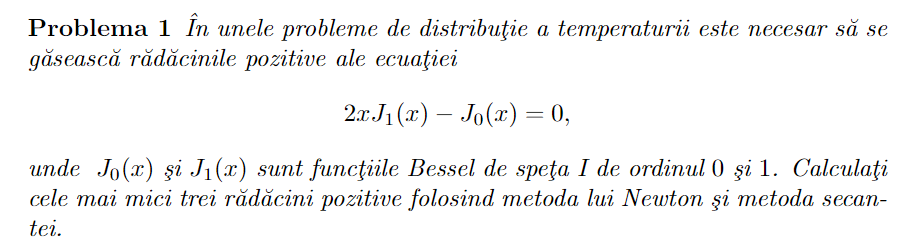

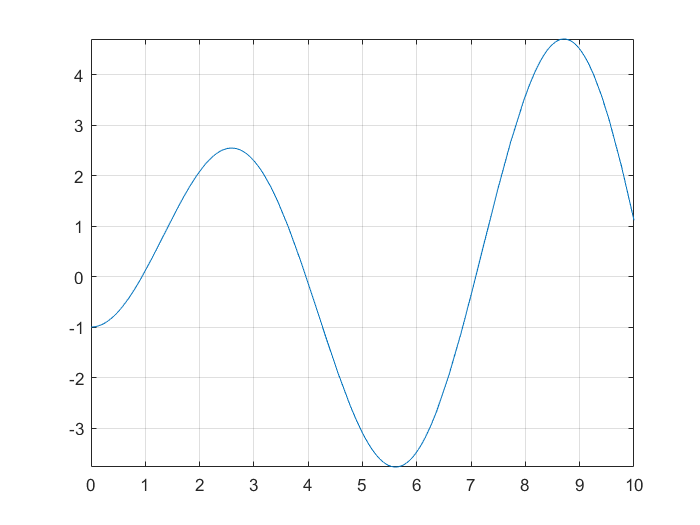

syms x;
f = @(x) 2.*x.*besselj(1, x) - besselj(0, x);
fd = @(x) 3.*besselj(1, x) - 2.*x.*(besselj(1, x)./x - besselj(0, x));
ea = 0;
er = 1e-9;

fplot(f, [0, 10])
grid on


z1 = Newton(f, fd, 0.9, ea, er)

z1 = 0.9408

z2 = Newton(f, fd, 4, ea, er)

z2 = 3.9594

z3 = Newton(f, fd, 7, ea, er)

z3 = 7.0864


x0 = [0, 4, 7];
x1 = [1, 5, 8];
z1 = secanta(f, x0, x1, ea, er)

z1 =     0.9408    3.9594    7.0864


% metoda lui Newton
% f, fd - functia si derivata sa
% x0 - punctul de pornire
% ea, er - eroarea absoluta si eroarea relativa
% output : z - solutia aproximata

function z = Newton(f, fd, x0, ea, er)
    maxIter = 50;
    xv = x0;
    for k = 1:maxIter
        xc = xv - f(xv)/fd(xv);
        if abs(xc - xv) < ea + er * abs(xc)
            z = xc;
            return
        end
        xv = xc;
    end
end

% metoda secantei
% f - functia
% x0, x1 - puncte de pornire
% ea, er - eroarea absoluta si eroarea relativa
% output : z - solutia aproximata
function z = secanta(f, x0, x1, ea, er)
    maxIter = 50;
    xv = x0; 
    fv = f(xv); 
    xc = x1; 
    fc = f(xc);
    for k = 1:maxIter
        xn = xc - fc.*(xc - xv)./(fc - fv);
        if abs(xn - xc) < ea + er * xn
            z = xn;
            return
        end
        xv = xc; 
        fv = fc; 
        xc = xn; 
        fc = feval(f, xn);
    end
end